Define the set of control points $\mathbf{P}_i$:

P = [0 1 3 0 3 2];

Define the spline as cubic, and compute the size of the knot vector from the number of control points:

d = 3;

n = numel(P) - 1;

m = n + d + 1;

Define the knot vector $\mathbf{T} = [t_0,t_1,...,t_m]$:

T = [linspace(0,1,m + 1)];

Define a vector for the paramter $t$ over which to calculate the B-spline. The spline is only defined for $t \in [t_d, t_{m-d}]$. These are incremented by 1 since MATLAB is 1-indexed. There are 100 values of $t$ per knot-span, which is an arbitrary choice. Test and observe what happens if you try allowing $t \in [t_0, t_{m}]$.

t = linspace(T(d+1),T(m-d+1),100*(m-d));

Define the required basis functions for $j=0$, as given by the Cox–de Boor recursion formula $N_{i,0}(t) = 
        \begin{cases}
            1, & \text{if } t\in[t_i, t_{i+1}) \\
            0, & \text{otherwise}
        \end{cases}$

N_ti0 = zeros(numel(t),m);
for i = 1:m
    N_ti0(and(T(i) <= t,t < T(i+1)),i) = 1;
end

These two lines find the last non-zero basis function, and ensure it's final value is 1. This is because the last function is a special case, we want to include $t_m$ to terminate the spline correctly, but the recursion formula specifies that $N_{i,0}(t) =  1  \text{ if } t\in[t_i, t_{i+1})$. Hence we must find the last non-zero basis function and set it's value at $t_m$ to 1.

idx = find(any(N_ti0>0),1,'last');
N_ti0(end,idx) = 1;

Using these, the remaining basis functions can be calculated, up to $j=d$. $N_{i,j}(t)$ is accessed by calling N_tij(t,i,j). The first column is initialised to the values of $N_{i,0}(t)$ computed above. The remaining columns are then filled though two for loops. a and b are the first and second half of the recursion formula respectively, and are required to set those halves to 0 if the denominator is 0. Hence the equation being applied is:

$N_{i,j}(t) =aN_{i,j-1}(t)+bN_{i+1,j-1}(t)$; 

$a = 
        \begin{cases}
            \frac{t-t_i}{t_{i+j}-t_i}, & \text{if } t_{i+j}-t_i \neq0 \\
            0, & \text{otherwise}
        \end{cases}$ ; $b = 
        \begin{cases}
           \frac{t_{i+j+1}-t}{t_{i+j+1}-t_{i+1}}, & \text{if } t_{i+j+1}-t_{i+1} \neq0 \\
            0, & \text{otherwise}
        \end{cases}$


N_tij = zeros(numel(t),m,d+1);
N_tij(:,:,1) = N_ti0;
for j = 1:d
    for i = 1:m-j
        if (T(i+j)-T(i)) == 0
            a = 0;
        else
            a = ((t-T(i))/(T(i+j)-T(i)))';
        end
        if T(i+j+1)-T(i+1) == 0
            b = 0; 
        else
            b = ((T(i+j+1)-t)/(T(i+j+1)-T(i+1)))';
        end
        N_tij(:,i,j+1) = a .* N_tij(:,i,j) + b .* N_tij(:,i+1,j);
    end
end

Plot the basis functions:

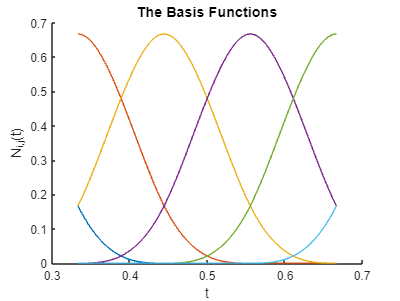

figure;
hold on
for i = 1:n+1
    plot(t,N_tij(:,i,d+1))
end
xlabel('t','fontsize',12);
ylabel('N_{i,j}(t)','fontsize',12);
title("The Basis Functions",'fontsize',12)

Create the spline, using $\mathbf{S}(t) = \sum_{i=0}^{n}N_{i,k}(t)\mathbf{P}_i$, applied with matrix multiplication:

S = P * N_tij(:,1:n+1,d+1)';

Plot the B-spline;

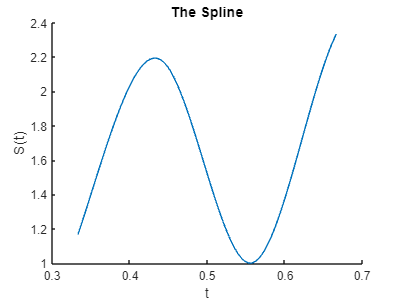

figure
hold on
plot(t,S);
xlabel('t','fontsize',12);
ylabel('S(t)','fontsize',12);
title("The Spline",'fontsize',12);